# create downsampled vector of all aluminum times without the artifact times


run(params_path)

experiment = auditory_ephys_exp(params_path);

Choose csv file for the whisking camera
Choose csv file for the face camera


data = load_open_ephys_binary([exp_path,'/experiment1/recording1/structure.oebin'],'continuous',1,'mmap');
aud_data = data.Data.Data.mapped(32 + mic,:)

aud_data = 1×67777280 int16 row vector
   425   440   443   477   413   473   456   470   465   443   407   395   466   451   431   426   435   434   427   425   473   419   407   456   411   429   465   435   483   458   489   459   415   413   474   435   443   422   397   487   424   431   431   471   487   467   498   478   451   455


% find time samples in video based on whiskers for both whiskers and face
whiskingStart = experiment.Cams.whsiking.csv_start_frame

whiskingStart = 402

expLength = length(data.Data.Data.mapped)

expLength = 67777280

whiskingEnd = find(experiment.Cams.whsiking.csv_aligned_frames < expLength);
whiskingEnd = whiskingEnd(end)

whiskingEnd = 902439

whiskingVector = [whiskingStart:whiskingEnd]

whiskingVector =    402   403   404   405   406   407   408   409   410   411   412   413   414   415   416   417   418   419   420   421   422   423   424   425   426   427   428   429   430   431   432   433   434   435   436   437   438   439   440   441   442   443   444   445   446   447   448   449   450   451


sampleVector = experiment.Cams.whsiking.csv_aligned_frames(whiskingVector)

sampleVector =        74828
       74966
       75038
       75115
       75211
       75266
       75342
       75414
       75486
       75561



[~,faceStart] = min(abs(experiment.Cams.face.csv_aligned_frames - sampleVector(1)))

faceStart = 101

faceEnd = find(experiment.Cams.face.csv_aligned_frames < expLength);
faceEnd = faceEnd(end);
faceVector = [faceStart:faceEnd]

faceVector =    101   102   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119   120   121   122   123   124   125   126   127   128   129   130   131   132   133   134   135   136   137   138   139   140   141   142   143   144   145   146   147   148   149   150


fullSampleVector = sampleVector(1):expLength'

fullSampleVector =        74828       74829       74830       74831       74832       74833       74834       74835       74836       74837       74838       74839       74840       74841       74842       74843       74844       74845       74846       74847       74848       74849       74850       74851       74852       74853       74854       74855       74856       74857       74858       74859       74860       74861       74862       74863       74864       74865       74866       74867       74868       74869       74870       74871       74872       74873       74874       74875       74876       74877


% Extract aluminum times
artifactStart = experiment.Conditions.artifact_times(2) * 30

artifactStart = 75000

artifactEnd = experiment.Conditions.artifact_times(1) * 30

artifactEnd = 90000

all_times = [experiment.Conditions.all_changes + artifactStart,[experiment.Conditions.all_changes(2:end);sampleVector(end)]-artifactEnd]

all_times = 34×2 int64 matrix
    4780464    6505018
    6670018    8394572
    8559572   10272128
   10437128   12149685
   12314685   14033243
   14198243   15910800
   16075800   17800355
   17965355   19677955
   19842955   21567509
   21732509   23457064


aluminumTimes = all_times(experiment.Conditions.condition_classification == 1,:)

aluminumTimes = 15×2 int64 matrix
   10437128   12149685
   12314685   14033243
   16075800   17800355
   19842955   21567509
   25499620   27218179
   31150290   32874844
   34917444   36630001
   36795001   38513559
   48102340   49814940
   49979940   51704494


% create idx vector for aluminum
aluminumInd = []


aluminumInd =

     []



for al = 1:length(aluminumTimes)
    tempInd = find(sampleVector > aluminumTimes(al,1) & sampleVector < aluminumTimes(al,2))
    aluminumInd = [aluminumInd;tempInd]
end

tempInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       163067
      163068
      163069
      163070
      163071
      163072
      163073
      163074
      163075
      163076


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       213183
      213184
      213185
      213186
      213187
      213188
      213189
      213190
      213191
      213192


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       263372
      263373
      263374
      263375
      263376
      263377
      263378
      263379
      263380
      263381


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       338741
      338742
      338743
      338744
      338745
      338746
      338747
      338748
      338749
      338750


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       414032
      414033
      414034
      414035
      414036
      414037
      414038
      414039
      414040
      414041


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       464225
      464226
      464227
      464228
      464229
      464230
      464231
      464232
      464233
      464234


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       489242
      489243
      489244
      489245
      489246
      489247
      489248
      489249
      489250
      489251


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       639902
      639903
      639904
      639905
      639906
      639907
      639908
      639909
      639910
      639911


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       664919
      664920
      664921
      664922
      664923
      664924
      664925
      664926
      664927
      664928


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       740210
      740211
      740212
      740213
      740214
      740215
      740216
      740217
      740218
      740219


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       765225
      765226
      765227
      765228
      765229
      765230
      765231
      765232
      765233
      765234


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       790238
      790239
      790240
      790241
      790242
      790243
      790244
      790245
      790246
      790247


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       815254
      815255
      815256
      815257
      815258
      815259
      815260
      815261
      815262
      815263


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       890535
      890536
      890537
      890538
      890539
      890540
      890541
      890542
      890543
      890544


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


full_aluminumInd =[];
for al = 1:length(aluminumTimes)
    tempIndA = find(fullSampleVector > aluminumTimes(al,1) & fullSampleVector < aluminumTimes(al,2));
    full_aluminumInd = [full_aluminumInd,tempIndA];
end

% create samplevector for aluminum
aluminumVector = sampleVector(aluminumInd)

aluminumVector =     10437131
    10437194
    10437277
    10437350
    10437430
    10437497
    10437581
    10437650
    10437729
    10437797


% create video frame whisker vector
aluminumWhiskerVector = whiskingVector(aluminumInd)'

aluminumWhiskerVector =       138454
      138455
      138456
      138457
      138458
      138459
      138460
      138461
      138462
      138463


% create video frame face vector
%aluminumFaceVector = faceVector(aluminumInd)'
fullAluminumVector = fullSampleVector(full_aluminumInd)';

## **create matrix for prediction with linear regression**

### **The model is a matrix with the following rows as variables and columuns as observations:**

- ** Encoder**

- **whiskingMotion_1**

- **whisking motSVD_0 (10 first)**

- **whisking motSVD_1 (10 first)**

- **faceMotion_1**

- **face motSVD_1 (10 first)**

- **Running from face camera**

**Predictions should be done on a matrix ordered the same why**

**The output will be a vector of the sound from open ephys sampled by the sampleVector and threshold **

% get the sound vector 
%aud_data = data.Data.Data.mapped(34,:)

[b,a] = butter(3,[500]/15000,'high')

b =     0.9005   -2.7016    2.7016   -0.9005


a =     1.0000   -2.7907    2.6027   -0.8110


aud_data = filtfilt(b,a,double(aud_data))

aud_data = 	1.0e+03 *

    0.0035    0.0173    0.0191    0.0519   -0.0133    0.0455    0.0273    0.0402    0.0341    0.0110   -0.0260   -0.0390    0.0310    0.0151   -0.0058   -0.0117   -0.0035   -0.0053   -0.0131   -0.0159    0.0314   -0.0233   -0.0360    0.0123   -0.0333   -0.0159    0.0195   -0.0111    0.0364    0.0109    0.0414    0.0109   -0.0336   -0.0360    0.0246   -0.0148   -0.0072   -0.0285   -0.0538    0.0359   -0.0273   -0.0205   -0.0207    0.0191    0.0350    0.0150    0.0459    0.0259   -0.0010    0.0030


% get the aluminum sound vector 
%aud_data = aud_data(aluminumVector)

% clean artifacts clipping
aud_data(aud_data > 1000 | aud_data < -1000) = 0;

% clean data below threshold
aud_data = abs(aud_data)

aud_data =     3.4959   17.2851   19.0738   51.8682   13.3257   45.4973   27.3420   40.2120   34.1105   11.0397   25.9988   39.0041   31.0241   15.0859    5.8194   11.6925    3.5344    5.3463   13.1295   15.8852   31.3853   23.3191   35.9993   12.3438   33.2904   15.9022   19.5080   11.0597   36.3946   10.8711   41.3700   10.8914   33.5644   35.9971   24.5938   14.7910    7.1508   28.4843   53.7905   35.9322   27.3147   20.5296   20.7110   19.1426   35.0322   14.9585   45.9218   25.9213    1.0439    3.0242


aud_data = normalize(aud_data,'range')

aud_data =     0.0035    0.0173    0.0191    0.0519    0.0133    0.0455    0.0273    0.0402    0.0341    0.0110    0.0260    0.0390    0.0310    0.0151    0.0058    0.0117    0.0035    0.0053    0.0131    0.0159    0.0314    0.0233    0.0360    0.0123    0.0333    0.0159    0.0195    0.0111    0.0364    0.0109    0.0414    0.0109    0.0336    0.0360    0.0246    0.0148    0.0072    0.0285    0.0538    0.0359    0.0273    0.0205    0.0207    0.0191    0.0350    0.0150    0.0459    0.0259    0.0010    0.0030


experiment.sound_events.fullSound = aud_data;

aud_data_cleaned = aud_data(fullAluminumVector)

aud_data_cleaned =     0.0063    0.0262    0.0291    0.0591    0.0270    0.0270    0.0790    0.0111    0.0309    0.0392    0.0033    0.0365    0.0076    0.0142    0.0449    0.0077    0.0346    0.0061    0.0852    0.0235    0.0032    0.0221    0.0445    0.0572    0.0868    0.0345    0.0028    0.0099    0.0056    0.0727    0.0390    0.0253    0.0015    0.0623    0.0159    0.0459    0.0343    0.0724    0.0565    0.0306    0.0394    0.0374    0.0104    0.0005    0.0094    0.0342    0.0541    0.0163    0.0547    0.0230


%aud_data_cleaned(aud_data_cleaned < 0.1) = 0

figure; plot(aud_data_cleaned)

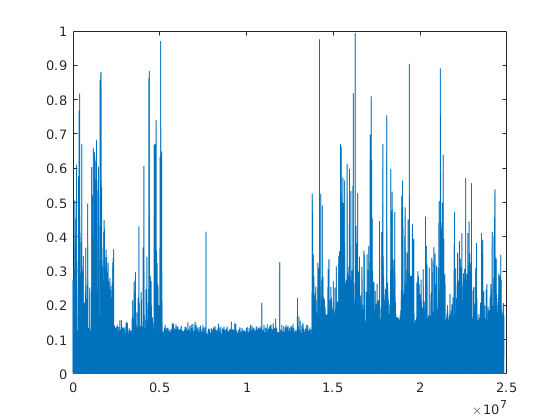

% get encoder data and high pass filter 
encoder_data = data.Data.Data.mapped(32 + encoder,:)

[b,a] = butter(3,[2]/30000,'high')
encoder_data = filtfilt(b,a,double(encoder_data))

% add encoder to the modal and prediction matrices

encoder_data = 1×67777280 int16 row vector
   20533   20542   20543   20547   20519   20539   20531   20537   20535   20547   20545   20547   20547   20535   20539   20534   20555   20538   20551   20527   20545   20547   20545   20542   20537   20529   20527   20537   20539   20537   20539   20539   20531   20523   20547   20536   20533   20537   20528   20546   20539   20544   20538   20544   20541   20543   20543   20546   20547   20543


%modelMatrix = encoder_data(aluminumVector)

b =     0.9998   -2.9994    2.9994   -0.9998


a =     1.0000   -2.9996    2.9992   -0.9996


%predictionMatrix = encoder_data(sampleVector)

encoder_data = 	1.0e+04 *

    0.0002    0.0011    0.0012    0.0016   -0.0012    0.0008   -0.0000    0.0006    0.0004    0.0016    0.0014    0.0016    0.0016    0.0004    0.0008    0.0003    0.0024    0.0007    0.0020   -0.0004    0.0014    0.0016    0.0014    0.0011    0.0006   -0.0002   -0.0004    0.0006    0.0008    0.0006    0.0008    0.0008   -0.0000   -0.0008    0.0016    0.0005    0.0002    0.0006   -0.0003    0.0015    0.0008    0.0013    0.0007    0.0013    0.0010    0.0012    0.0012    0.0015    0.0016    0.0012


modelMatrix = encoder_data(fullAluminumVector)
predictionMatrix = encoder_data(fullSampleVector)

%use fullAluminumInd

% import the whisking moiton vectors
[file,path] = uigetfile();

modelMatrix = 	1.0e+04 *

   -0.0330   -0.0330   -0.0340   -0.0338   -0.0329   -0.0323   -0.0321   -0.0329   -0.0344   -0.0334   -0.0333   -0.0339   -0.0353   -0.0328   -0.0328   -0.0334   -0.0332   -0.0328   -0.0328   -0.0332   -0.0328   -0.0328   -0.0334   -0.0343   -0.0333   -0.0335   -0.0339   -0.0341   -0.0345   -0.0345   -0.0315   -0.0326   -0.0328   -0.0336   -0.0331   -0.0332   -0.0334   -0.0326   -0.0328   -0.0326   -0.0330   -0.0336   -0.0343   -0.0329   -0.0328   -0.0329   -0.0338   -0.0341   -0.0343   -0.0338


cd(path)

predictionMatrix = 	1.0e+04 *

    0.0007    0.0009   -0.0023   -0.0004    0.0003   -0.0004    0.0005    0.0008    0.0017    0.0003   -0.0001   -0.0015   -0.0010    0.0007    0.0003    0.0008   -0.0003    0.0008    0.0009    0.0009   -0.0007    0.0007    0.0001    0.0015    0.0009    0.0005    0.0017   -0.0023    0.0001   -0.0001   -0.0013   -0.0004   -0.0000   -0.0001    0.0015   -0.0009    0.0005    0.0017    0.0009    0.0005    0.0005   -0.0004   -0.0006    0.0002    0.0007    0.0001   -0.0003    0.0017    0.0013   -0.0007


load(file,'motSVD_1','motion_1','motSVD_0')
try

alumFFromSampleVector =     10437129    10437130    10437131    10437132    10437133    10437134    10437135    10437136    10437137    10437138    10437139    10437140    10437141    10437142    10437143    10437144    10437145    10437146    10437147    10437148    10437149    10437150    10437151    10437152    10437153    10437154    10437155    10437156    10437157    10437158    10437159    10437160    10437161    10437162    10437163    10437164    10437165    10437166    10437167    10437168    10437169    10437170    10437171    10437172    10437173    10437174    10437175    10437176    10437177    10437178


    load(file,'motSVD_2')
catch 
    'no motSVD_2'
end

% Create a matrix of SVD and motion of whisker camera and resample for the
% model creation
motion4Resample = double(motion_1(whiskingVector));
motSVD4Resample = double(motSVD_1(whiskingVector,20));

clear motion_1 motSVD_1 data encoder_data aud_data

%resample vector and matrix
motionResampled = resample(motion4Resample,length(fullSampleVector),length(motion4Resample))

% if ~isempty(motSVD_0)% add motion and motSVDs to the modal and prediciton matrices
%     modelMatrix(2,:) = motion_1(aluminumWhiskerVector)
%     predictionMatrix(2,:) = motion_1(whiskingVector)
%     modelMatrix(3:12,:) = motSVD_0(aluminumWhiskerVector,1:10)'

Error using resample
Expected input number 1, X, to be one of these types:

double

Instead its type was single.

Error in resample>orientToNdim (line 923)
validateattributes(x,{'double'},{'nonempty','nonsparse'},'resample','X',1);

Error in resample (line 174)
    [xIn, dimIn] = orientToNdim (varargin{1}, Dim);

%     predictionMatrix(3:12,:) = motSVD_0(whiskingVector,1:10)'
%     modelMatrix(13:22,:) = motSVD_1(aluminumWhiskerVector,1:10)'
%     predictionMatrix(13:22,:) = motSVD_1(whiskingVector,1:10)'
%     ind = 23
% elseif exist('motSVD_2')
%     modelMatrix(2,:) = motion_1(aluminumWhiskerVector)
%     predictionMatrix(2,:) = motion_1(whiskingVector)
%     modelMatrix(3:12,:) = motSVD_1(aluminumWhiskerVector,1:10)'
%     predictionMatrix(3:12,:) = motSVD_1(whiskingVector,1:10)'
%     modelMatrix(13:22,:) = motSVD_2(aluminumWhiskerVector,1:10)'
%     predictionMatrix(13:22,:) = motSVD_2(whiskingVector,1:10)'
%     ind = 23
% else
%     modelMatrix(2,:) = motion_1(aluminumWhiskerVector)
%     predictionMatrix(2,:) = motion_1(whiskingVector)
%     modelMatrix(3:22,:) = motSVD_1(aluminumWhiskerVector,1:20)'
%     predictionMatrix(3:22,:) = motSVD_1(whiskingVector,1:20)'
%     ind = 13
% end


% import data from face video
clear motion_1 motion_0 motSVD_1 motSVD_0
[file,path] = uigetfile();
cd(path)
load(file, 'motSVD_1','motion_1','running_0')

% add motion and motSVDs to the modal and prediciton matrices
modelMatrix(ind,:) = motion_1(aluminumFaceVector)
predictionMatrix(ind,:) = motion_1(faceVector)
modelMatrix(ind+1:ind+10,:) = motSVD_1(aluminumFaceVector,1:10)'
predictionMatrix(ind+1:ind+10,:) = motSVD_1(faceVector,1:10)'
modelMatrix(ind+11:ind+12,:) = running_0(aluminumFaceVector,1:2)'
predictionMatrix(ind+11:ind+12,:) = running_0(faceVector,1:2)'

% save the model and prediction vectors 
save('model_matrices.mat','experiment','modelMatrix',"aud_data_cleaned",'predictionMatrix','sampleVector','aluminumWhiskerVector')

% load model and prediction if needed
cd('/home/ben/Z/FVB/270721/849')  

                 
load('model_matrices.mat')

% create traintest spli idx for testing model
modelPart = cvpartition(length(modelMatrix),"HoldOut",0.1)
idxTrain = training(modelPart)
idxTest = test(modelPart)

% split data to train test
modelTrain = modelMatrix(:,idxTrain)
modelTest = modelMatrix(:,idxTest)

aud_data_Train = aud_data_cleaned(idxTrain)
aud_data_test = aud_data_cleaned(idxTest)

%aud_data_cleaned = normalize(aud_data_cleaned,'range')

% savr model to the experiment object
experiment.predictionModel = trainedModel;

% Get predictions from regression learner (bagged tree ensamble)
y = trainedModel.predictFcn(predictionMatrix)

% find all y values aboe threshold and find the start of each event 

[times] = event_detection(experiment.sound_events.fullSound,30000*0.4)



% find events sample time
times_prediction = times
times = sampleVector(times);

experiment.predictedSound.y = y
experiment.predictedSound.sampleVector = sampleVector
experiment.predictedSound.events.all = times_prediction

% Add the events top the experiment object
experiment.sound_events.all = times

artifactStart = experiment.Conditions.artifact_times(2) * 30
artifactEnd = experiment.Conditions.artifact_times(1) * 30
all_times = [experiment.Conditions.all_changes + artifactStart,[experiment.Conditions.all_changes(2:end);sampleVector(end)]-artifactEnd]

all_times = all_times(1:22,:)

times = experiment.sound_events.all;
times_prediction = experiment.predictedSound.events.all

`Divide the events to the experiment condition`

% Aluminum times
aluminumTimes = all_times(experiment.Conditions.condition_classification(1:18) == 1,:)
aluminumEvents = []
experiment.predictedSound.events.aluminum = [];
for al = 1:length(aluminumTimes)
    tempEvents = times(find(times > aluminumTimes(al,1) & times < aluminumTimes(al,2)))
    tempPredict = times_prediction(find(times > aluminumTimes(al,1) & times < aluminumTimes(al,2)))'
    aluminumEvents = [aluminumEvents;tempEvents]
    experiment.predictedSound.events.aluminum = [experiment.predictedSound.events.aluminum;tempPredict]
end

% non times
nonTimes = all_times(experiment.Conditions.condition_classification(1:18) == 3,:)
experiment.predictedSound.events.non = [];
nonEvents = []
for non = 1:length(nonTimes)
    tempInd = times(find(times > nonTimes(non,1) & times < nonTimes(non,2)))
    tempPredict = times_prediction(find(times > nonTimes(non,1) & times < nonTimes(non,2)))'
    nonEvents = [nonEvents;tempInd]
    experiment.predictedSound.events.non = [experiment.predictedSound.events.non;tempPredict];
end

% muted times
mutedTimes = all_times(experiment.Conditions.condition_classification(1:18) == 2,:)
experiment.predictedSound.events.muted = [];
mutedEvents = []
for mut = 1:length(mutedTimes)
    tempInd = times(find(times > mutedTimes(mut,1) & times < mutedTimes(mut,2)))
    tempPredict = times_prediction(find(times > mutedTimes(mut,1) & times < mutedTimes(mut,2)))'
    mutedEvents = [mutedEvents;tempInd]
    experiment.predictedSound.events.muted = [experiment.predictedSound.events.muted;tempPredict];
end

timeWind = 1;
numBins = 20;

rasters_aluminum = {}
psth_aluminum = []
for un = 1:length(experiment.Units.good.id)
    rasters_aluminum{un} = createRaster(aluminumEvents,experiment.Units.good.times(un,:),timeWind);
    title(['Predicted aluminum events unit id',num2str(un)])
    psth_aluminum(un,:) = psth(rasters_aluminum{un},numBins);
end

rasters_muted = {}
psth_muted = []
for un = 1:length(experiment.Units.good.id)
    rasters_muted{un} = createRaster(mutedEvents,experiment.Units.good.times(un,:),timeWind);
    title(['Predicted muted events unit id',num2str(un)])
    psth_muted(un,:) = psth(rasters_muted{un},numBins);
end

rasters_non = {}
psth_non = []
for un = 1:length(experiment.Units.good.id)
    rasters_non{un} = createRaster(nonEvents,experiment.Units.good.times(un,:),timeWind);
    title(['Predicted muted events unit id',num2str(un)])
    psth_non(un,:) = psth(rasters_non{un},numBins);
end

rasters_aluminumMua = {}
psth_aluminumMua = []
for un = 1:length(experiment.Units.mua.id)
    rasters_aluminumMua{un} = createRaster(aluminumEvents,experiment.Units.mua.times(un,:),timeWind);
    title(['Predicted aluminum events unit id',num2str(un)])
    psth_aluminumMua(un,:) = psth(rasters_aluminumMua{un},numBins);
end

rasters_mutedMua = {}
psth_mutedMua = []
for un = 1:length(experiment.Units.mua.id)
    rasters_mutedMua{un} = createRaster(mutedEvents,experiment.Units.mua.times(un,:),timeWind);
    title(['Predicted muted events unit id',num2str(un)])
    psth_mutedMua(un,:) = psth(rasters_mutedMua{un},numBins);
end

rasters_nonMua = {}
psth_nonMua = []
for un = 1:length(experiment.Units.mua.id)
    rasters_nonMua{un} = createRaster(nonEvents,experiment.Units.mua.times(un,:),timeWind);
    title(['Predicted muted events unit id',num2str(un)])
    psth_nonMua(un,:) = psth(rasters_nonMua{un},numBins);
end

psth_aluminumAll = [psth_aluminum;psth_aluminumMua]

psth_mutedAll = [psth_muted;psth_mutedMua]
psth_nonAll = [psth_non;psth_nonMua]

aud_units = find(experiment.evokedEvents.pVal(:,2) == 1);
[~,time_vector] = psth(rasters_non{1},numBins);

mutSTD = std(psth_mutedAll(aud_units,:))/sqrt(length(aud_units))
alumSTD = std(psth_aluminumAll(aud_units,:))/sqrt(length(aud_units))
nonSTD = std(psth_nonAll(aud_units,:))/sqrt(length(aud_units))

figure; 
hold on     

plot(time_vector,mean(psth_aluminumAll(aud_units,:)),'LineWidth',2,'Color',experiment.color.Aluminum)
errorbar(time_vector,mean(psth_aluminumAll(aud_units,:)),alumSTD,'LineWidth',0.1,'Color',experiment.color.Aluminum)
hold on
plot(time_vector,mean(psth_mutedAll(aud_units,:)),'LineWidth',2,'Color',experiment.color.Muted)
errorbar(time_vector,mean(psth_mutedAll(aud_units,:)),mutSTD,'LineWidth',0.1,'Color',experiment.color.Muted)
plot(time_vector,mean(psth_nonAll(aud_units,:)),'LineWidth',2,'Color',experiment.color.noObject)
errorbar(time_vector,mean(psth_nonAll(aud_units,:)),nonSTD,'LineWidth',0.1,'Color',experiment.color.noObject)

meanSound.aluminumMean = meanMatrix(experiment.predictedSound.events.aluminum,1,400)
figure; plot(mean(y(meanSound.aluminumMean)))
hold on
meanSound.mutedMean = meanMatrix(experiment.predictedSound.events.muted,1,400)
plot(mean(y(meanSound.mutedMean)))
meanSound.nonMean = meanMatrix(experiment.predictedSound.events.non,1,400)
plot(mean(y(meanSound.nonMean)))

meanSound.aluminumMean = meanMatrix(aluminumEvents,1,30000);
figure; plot(mean(experiment.sound_events.fullSound(meanSound.aluminumMean)));
hold on;
meanSound.mutedMean = meanMatrix(mutedEvents,1,30000);
plot(mean(experiment.sound_events.fullSound(meanSound.mutedMean)));
meanSound.nonMean = meanMatrix(nonEvents,1,30000)
plot(mean(experiment.sound_events.fullSound(meanSound.nonMean)));

experiment.sound_events.aluminum = aluminumTimes;
experiment.sound_events.muted = mutedTimes;
experiment.sound_events.non = nonTimes;
experiment.PSTHs.alum = psth_aluminumAll;
experiment.PSTHs.muted = psth_mutedAll;
experiment.PSTHs.non = psth_nonAll;
%experiment.PSTHs.audUnits = aud_units;
experiment.PSTHs.time_vector = time_vector;

experiment.sound_events.aluminumEvents = aluminumEvents;
experiment.sound_events.mutedEvents = mutedEvents;
experiment.sound_events.nonEvents = nonEvents;

%params = '/home/ben/Z/Parameters_files/FVB/FVB103_270721_849.m';
run(params)

save([expName,'.mat'],'experiment')